%% =============================================================
%  Ideal CP-PLL (no noise) — Loop analysis v2
%  
%  Changes from v1:
%  [S2] Href = N*L/(1+L) = theta_out/theta_in
%  [I1] Frequency grid: logspace
%
%  Figures (5 total):
%    Fig 1 — Diagnostic: 6-subplot vector-form (L, Href, Hdiv)
%    Fig 2 — Open-loop Bode L(s) with fz/fp/fu/PM annotations
%    Fig 3 — Closed-loop |Hdiv| + |Herr| (tracking vs error rejection)
%    Fig 4 — Step responses (output phase + phase error)
%    Fig 5 — Frequency step response (Δfout + ΔVctrl)
% =============================================================
clear; clc; close all;

%% 1. PLL parameters
fref = 10e6;                  % reference clock frequency, Hz
N    = 10;                    % division ratio
Icp  = 45e-6;                 % charge pump current, A
Kpd  = Icp/(2*pi);            % PFD/CP gain, A/rad
Kvco = 2*pi*250e6;            % VCO gain, rad/(s·V)
R1   = 4.92e3;                % loop filter resistor, Ohm
C1   = 1.508e-10;             % capacitor C1, F
C2   = 1.167e-11;             % capacitor C2, F

fout = fref * N;              % output frequency, Hz
fprintf('Output frequency = %.2f MHz\n', fout/1e6);

Output frequency = 100.00 MHz



%% 2. Frequency grid (logarithmic)
f = logspace(log10(1e3), log10(300e6), 2000);
w = 2*pi*f;

%% 3. Vector-form loop transfer functions

% Loop filter transimpedance Z(jw)
Fw = (1 + 1i*w*R1*C1) ./ ((1i*w).^2 * R1*C1*C2 + 1i*w*(C1 + C2));

% Forward gain A(jw) = Kpd * Z * Kvco / (jw)
Aw = Kpd .* Fw .* Kvco ./ (1i*w);

% Feedback B = 1/N
Bw = 1/N;

% Open-loop gain L(jw) = A * B
Gw = Aw .* Bw;

% [S2] Closed-loop TFs
Hw     = Aw ./ (1 + Aw.*Bw);    % theta_out / theta_in  (DC gain = N)
Hw_div = Hw / N;                 % theta_div / theta_in  (DC gain = 1)

% Loop metrics
[~, idx_u] = min(abs(abs(Gw) - 1));
fu = f(idx_u);

fz = 1/(2*pi*R1*C1);
fp = (C1+C2)/(2*pi*R1*C1*C2);

PM_approx = (atan(fu/fz) - atan(fu/fp))/pi*180;

fprintf('\n=== Loop Metrics (vector form) ===\n');


=== Loop Metrics (vector form) ===


fprintf('Zero  fz = %.3f MHz\n', fz/1e6);

Zero  fz = 0.215 MHz


fprintf('Pole  fp = %.3f MHz\n', fp/1e6);

Pole  fp = 2.986 MHz


fprintf('Unity-gain fu = %.3f kHz\n', fu/1e3);

Unity-gain fu = 817.610 kHz


fprintf('Phase margin (approx) = %.1f deg\n', PM_approx);

Phase margin (approx) = 60.0 deg


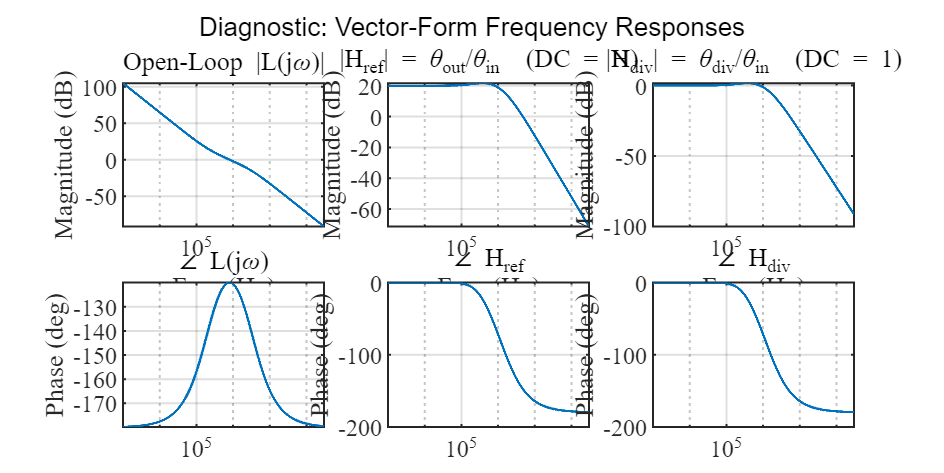


%% 4. tf objects for Bode and step

s = tf('s');

F_tf = (1 + s*R1*C1) / (s^2 * R1*C1*C2 + s*(C1 + C2));
A_tf = Kpd * F_tf * Kvco / s;
B_tf = 1/N;
L_tf = A_tf * B_tf;

Href_tf = A_tf / (1 + A_tf*B_tf);    % theta_out / theta_in  (DC = N)
Hdiv_tf = L_tf / (1 + L_tf);         % theta_div / theta_in  (DC = 1)
Herr_tf = 1 - Hdiv_tf;               % phase error / theta_in (DC = 0)

%% =========================================================================
%  FIGURES (5 total)
%% =========================================================================

%% --- Figure 1: Diagnostic 6-subplot (vector form) -------------------------

figure('Position', [100 100 1100 550]);

subplot(2,3,1);
semilogx(f, 20*log10(abs(Gw)), 'LineWidth', 1.3);
grid on; xlabel('Freq (Hz)'); ylabel('Magnitude (dB)');
title('Open-Loop |L(j\omega)|');

subplot(2,3,4);
semilogx(f, unwrap(angle(Gw))/pi*180, 'LineWidth', 1.3);
grid on; xlabel('Freq (Hz)'); ylabel('Phase (deg)');
title('\angle L(j\omega)');

subplot(2,3,2);
semilogx(f, 20*log10(abs(Hw)), 'LineWidth', 1.3);
grid on; xlabel('Freq (Hz)'); ylabel('Magnitude (dB)');
title('|H_{ref}| = \theta_{out}/\theta_{in}  (DC = N)');

subplot(2,3,5);
semilogx(f, unwrap(angle(Hw))/pi*180, 'LineWidth', 1.3);
grid on; xlabel('Freq (Hz)'); ylabel('Phase (deg)');
title('\angle H_{ref}');

subplot(2,3,3);
semilogx(f, 20*log10(abs(Hw_div)), 'LineWidth', 1.3);
grid on; xlabel('Freq (Hz)'); ylabel('Magnitude (dB)');
title('|H_{div}| = \theta_{div}/\theta_{in}  (DC = 1)');

subplot(2,3,6);
semilogx(f, unwrap(angle(Hw_div))/pi*180, 'LineWidth', 1.3);
grid on; xlabel('Freq (Hz)'); ylabel('Phase (deg)');
title('\angle H_{div}');

sgtitle('Diagnostic: Vector-Form Frequency Responses', 'FontSize', 13);

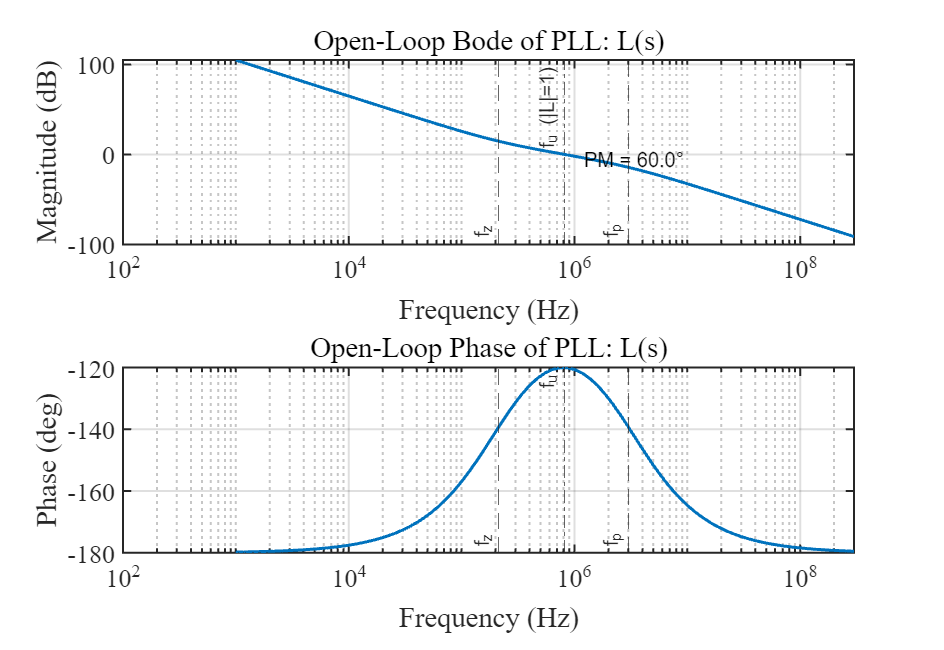


%% --- Figure 2: Open-loop Bode with annotations ----------------------------

[mag, phase, wout] = bode(L_tf, {2*pi*1e3, 2*pi*300e6});
mag   = squeeze(mag);
phase = squeeze(phase);
f_bode = wout / (2*pi);

[GM, PM, Wcg, Wcp] = margin(L_tf);
fu_Hz = Wcp / (2*pi);

figure('Position', [100 100 800 550]);

% Magnitude
subplot(2,1,1);
semilogx(f_bode, 20*log10(mag), 'LineWidth', 1.5);
hold on; grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Open-Loop Bode of PLL: L(s)');

xline(fz, '--', 'f_z', ...
    'LabelHorizontalAlignment', 'left', ...
    'LabelVerticalAlignment', 'bottom');
xline(fp, '--', 'f_p', ...
    'LabelHorizontalAlignment', 'left', ...
    'LabelVerticalAlignment', 'bottom');
xline(fu_Hz, '-.', 'f_u (|L|=1)', ...
    'LabelHorizontalAlignment', 'left', ...
    'LabelVerticalAlignment', 'top');

text(fu_Hz*1.5, -5, sprintf('PM = %.1f°', PM), ...
    'HorizontalAlignment', 'left', 'FontSize', 10);

% Phase
subplot(2,1,2);
semilogx(f_bode, phase, 'LineWidth', 1.5);
hold on; grid on;
xlabel('Frequency (Hz)');
ylabel('Phase (deg)');
title('Open-Loop Phase of PLL: L(s)');

xline(fz, '--', 'f_z', ...
    'LabelHorizontalAlignment', 'left', ...
    'LabelVerticalAlignment', 'bottom');
xline(fp, '--', 'f_p', ...
    'LabelHorizontalAlignment', 'left', ...
    'LabelVerticalAlignment', 'bottom');
xline(fu_Hz, '-.', 'f_u', ...
    'LabelHorizontalAlignment', 'left', ...
    'LabelVerticalAlignment', 'top');


fprintf('\n=== Exact margins from margin(L) ===\n');


=== Exact margins from margin(L) ===


fprintf('Gain margin GM  = %.2f dB at %.3e rad/s\n', 20*log10(GM), Wcg);

Gain margin GM  = -Inf dB at 0.000e+00 rad/s


fprintf('Phase margin PM = %.2f deg at %.3e rad/s (fu = %.3f kHz)\n', PM, Wcp, fu_Hz/1e3);

Phase margin PM = 59.99 deg at 5.124e+06 rad/s (fu = 815.589 kHz)


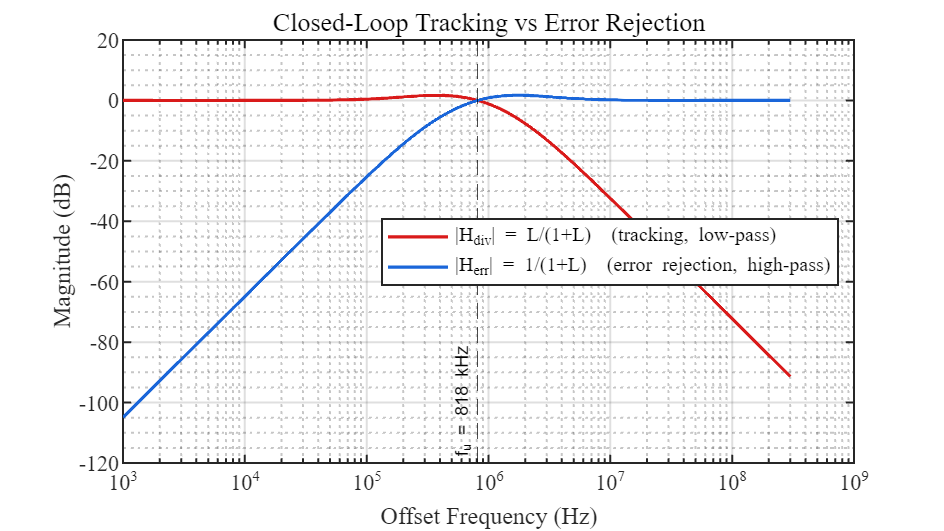


%% --- Figure 3: Closed-loop |Href| + |Herr| --------------------------------
%  Shows the complementary tracking / error-rejection behaviour.
%  |Href|: low-pass (tracks reference within bandwidth)
%  |Herr|: high-pass (rejects reference disturbances above bandwidth)

% Evaluate Herr on the vector grid for consistent plotting
Herr_w = 1 - Hw_div;   % = 1 - L/(1+L) = 1/(1+L)

figure('Position', [100 100 800 450]);

semilogx(f, 20*log10(abs(Hw_div)), '-', 'Color', [0.85 0.1 0.1], 'LineWidth', 1.6);
hold on;
semilogx(f, 20*log10(abs(Herr_w)), '-', 'Color', [0.1 0.4 0.85], 'LineWidth', 1.6);

xline(fu, '--k', sprintf('f_u = %.0f kHz', fu/1e3), ...
      'LabelHorizontalAlignment', 'left', ...
      'LabelVerticalAlignment', 'bottom', 'FontSize', 9);

grid on; grid minor;
set(gca, 'FontSize', 11);
xlabel('Offset Frequency (Hz)', 'FontSize', 12);
ylabel('Magnitude (dB)', 'FontSize', 12);
title('Closed-Loop Tracking vs Error Rejection', 'FontSize', 13);
legend({'|H_{div}| = L/(1+L)  (tracking, low-pass)', ...
        '|H_{err}| = 1/(1+L)  (error rejection, high-pass)'}, ...
       'FontSize', 10, 'Location', 'east');


%% --- Figure 4: Step responses (output phase + phase error) -----------------

wn_est = sqrt(Kpd*Kvco/(N*C1));
t_end  = 5 / (0.7 * wn_est);
t      = linspace(0, t_end, 2000);

figure('Position', [100 100 800 550]);

% (a) Output phase
subplot(2,1,1);
step(Href_tf, t);
grid on;
title(sprintf('Step response of H_{ref}(s) = \\theta_{out}/\\theta_{in}   (final value \\rightarrow N = %d)', N));
xlabel('Time (s)');
ylabel('Output phase (rad)');

% (b) Phase error
subplot(2,1,2);
step(Herr_tf, t);
grid on;
title('Step response of H_{err}(s) = 1 - L/(1+L)   (final value \rightarrow 0)');
xlabel('Time (s)');
ylabel('Phase error (rad)');


%% === Console: step info ===================================================

info_div = stepinfo(Hdiv_tf);
fprintf('\n=== Step response info (Hdiv = theta_div/theta_in, DC=1) ===\n');


=== Step response info (Hdiv = theta_div/theta_in, DC=1) ===


fprintf('Rise time     = %.3e s\n', info_div.RiseTime);

Rise time     = 2.307e-07 s


fprintf('Settling time = %.3e s\n', info_div.SettlingTime);

Settling time = 1.910e-06 s


fprintf('Overshoot     = %.2f %%\n', info_div.Overshoot);

Overshoot     = 18.65 %


fprintf('Peak time     = %.3e s\n', info_div.PeakTime);

Peak time     = 6.259e-07 s



info_out = stepinfo(Href_tf);
fprintf('\n=== Step response info (Href = theta_out/theta_in, DC=N) ===\n');


=== Step response info (Href = theta_out/theta_in, DC=N) ===


fprintf('Rise time     = %.3e s\n', info_out.RiseTime);

Rise time     = 2.307e-07 s


fprintf('Settling time = %.3e s\n', info_out.SettlingTime);

Settling time = 1.910e-06 s


fprintf('Overshoot     = %.2f %%\n', info_out.Overshoot);

Overshoot     = 18.65 %


fprintf('Peak time     = %.3e s\n', info_out.PeakTime);

Peak time     = 6.259e-07 s



fprintf('\nNote: Href and Hdiv have identical dynamics.\n');


Note: Href and Hdiv have identical dynamics.


fprintf('      They differ only in DC gain: Href -> N=%d, Hdiv -> 1.\n', N);

      They differ only in DC gain: Href -> N=10, Hdiv -> 1.



%% --- Figure 5: Frequency Step Response ------------------------------------
%  A step change in reference frequency (Δfref) at t=0.
%  Computes:
%    (a) Output frequency transient Δfout(t)
%    (b) Control voltage transient ΔVctrl(t)
%
%  Physics:
%    For a freq step, θ_in(t) = 2π·Δfref·t  (phase ramp)
%    Δfout(t) = Δfref × [step response of Href(s)]
%    ΔVctrl(t) = lsim(Kpd·Z(s)·Herr(s), θ_in(t), t)
%
%  Steady-state:
%    Δfout_ss   = N · Δfref
%    ΔVctrl_ss  = 2π · N · Δfref / Kvco

% --- Step parameters ---
delta_fref = 1e6;                             % 1 MHz reference step
delta_fout_ss = N * delta_fref;               % expected Δfout (10 MHz)
delta_Vctrl_ss = 2*pi*N*delta_fref / Kvco;    % expected ΔVctrl (40 mV)

fprintf('\n=== Frequency Step Parameters ===\n');


=== Frequency Step Parameters ===


fprintf('Δfref     = %.1f MHz\n', delta_fref/1e6);

Δfref     = 1.0 MHz


fprintf('Δfout_ss  = %.1f MHz  (= N × Δfref)\n', delta_fout_ss/1e6);

Δfout_ss  = 10.0 MHz  (= N × Δfref)


fprintf('ΔVctrl_ss = %.1f mV   (= 2π·N·Δfref / Kvco)\n', delta_Vctrl_ss*1e3);

ΔVctrl_ss = 40.0 mV   (= 2π·N·Δfref / Kvco)


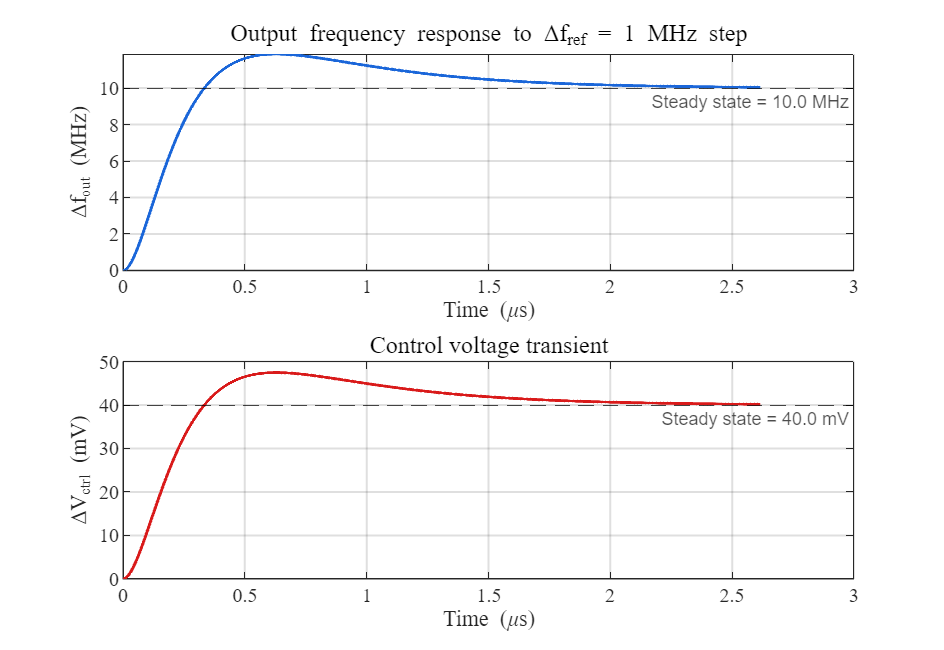


% --- Time axis (reuse t_end from step response) ---
t_freq = linspace(0, t_end, 4000);
dt_freq = t_freq(2) - t_freq(1);

% --- (a) Output frequency: Δfout(t) = Δfref × step(Href) ---
%  Since Href has DC gain = N, step(Href) → N, so Δfout → N·Δfref ✓
[y_href, ~] = step(Href_tf, t_freq);
delta_fout_t = delta_fref * y_href;

% --- (b) Control voltage: ΔVctrl via lsim ---
%  Transfer: θ_in → Vctrl = Kpd · Z(s) · Herr(s)
%  Input:    θ_in(t) = 2π · Δfref · t  (phase ramp from freq step)
H_vctrl_tf = Kpd * F_tf * Herr_tf;
theta_in_ramp = 2*pi * delta_fref * t_freq;
delta_Vctrl_t = lsim(H_vctrl_tf, theta_in_ramp, t_freq);

% --- Plot ---
figure('Position', [100 100 800 550]);

% (a) Frequency transient
subplot(2,1,1);
plot(t_freq*1e6, delta_fout_t/1e6, 'LineWidth', 1.5, 'Color', [0.1 0.4 0.85]);
hold on;
yline(delta_fout_ss/1e6, '--k', sprintf('Steady state = %.1f MHz', delta_fout_ss/1e6), ...
      'LabelHorizontalAlignment', 'right', ...
      'LabelVerticalAlignment', 'bottom', 'FontSize', 9);
grid on;
set(gca, 'FontSize', 10);
xlabel('Time (\mus)');
ylabel('\Deltaf_{out} (MHz)');
title(sprintf('Output frequency response to \\Deltaf_{ref} = %.0f MHz step', delta_fref/1e6), ...
      'FontSize', 12);

% (b) Vctrl transient
subplot(2,1,2);
plot(t_freq*1e6, delta_Vctrl_t*1e3, 'LineWidth', 1.5, 'Color', [0.85 0.1 0.1]);
hold on;
yline(delta_Vctrl_ss*1e3, '--k', sprintf('Steady state = %.1f mV', delta_Vctrl_ss*1e3), ...
      'LabelHorizontalAlignment', 'right', ...
      'LabelVerticalAlignment', 'bottom', 'FontSize', 9);
grid on;
set(gca, 'FontSize', 10);
xlabel('Time (\mus)');
ylabel('\DeltaV_{ctrl} (mV)');
title('Control voltage transient', 'FontSize', 12);


% --- Console: settling metrics ---
% Find 2% settling for Δfout
target_2pct = 0.02 * delta_fout_ss;
settled = abs(delta_fout_t - delta_fout_ss) <= target_2pct;
idx_settle = find(settled, 1, 'first');
if ~isempty(idx_settle)
    t_settle_freq = t_freq(idx_settle);
    fprintf('\nFreq step settling (±2%%): %.3f μs\n', t_settle_freq*1e6);
else
    fprintf('\nFreq step: not settled within simulation window\n');
end


Freq step settling (±2%): 0.323 μs



% Peak overshoot of Δfout
[peak_fout, idx_peak] = max(delta_fout_t);
overshoot_freq = (peak_fout - delta_fout_ss) / delta_fout_ss * 100;
fprintf('Freq step overshoot: %.2f%%  (peak = %.2f MHz at t = %.3f μs)\n', ...
        overshoot_freq, peak_fout/1e6, t_freq(idx_peak)*1e6);

Freq step overshoot: 18.65%  (peak = 11.87 MHz at t = 0.629 μs)



% Peak ΔVctrl
[peak_vctrl, idx_vp] = max(delta_Vctrl_t);
overshoot_vctrl = (peak_vctrl - delta_Vctrl_ss) / delta_Vctrl_ss * 100;
fprintf('Vctrl overshoot:     %.2f%%  (peak = %.2f mV at t = %.3f μs)\n', ...
        overshoot_vctrl, peak_vctrl*1e3, t_freq(idx_vp)*1e6);

Vctrl overshoot:     18.65%  (peak = 47.46 mV at t = 0.629 μs)
